a = 1+mod(137,3);

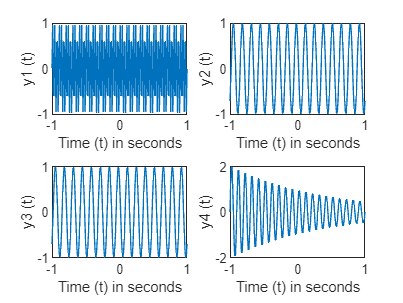

% Q1)
subplot(2,2,1);
t = -1:0.01:1;
y1 = sin(20*pi*a*t);
plot(t, y1)
xlabel('Time (t) in seconds')
ylabel('y1 (t)')


subplot(2,2,2);
t = -1:0.01:1;
y2 = cos(5*pi*a*t + (pi/4));
plot(t, y2)
xlabel('Time (t) in seconds')
ylabel('y2 (t)')


subplot(2,2,3);
y3 = exp(-2*a*t);
plot(t, y2)
xlabel('Time (t) in seconds')
ylabel('y3 (t)')

subplot(2,2,4);
y4 = exp(-0.25*a*t) .* sin(20*pi*t);
plot(t, y4)
xlabel('Time (t) in seconds')
ylabel('y4 (t)')

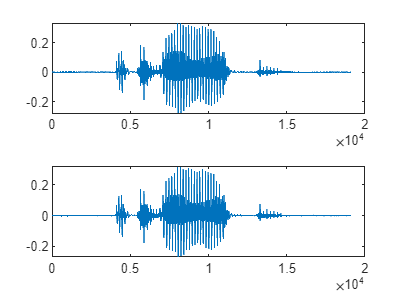

%Q2
[s_n,Fs2] = audioread("speech.wav");
F = 250 * a;
y = s_n .* cos(2*pi*F/Fs2);
subplot(2,1,1);
plot(s_n);
subplot(2,1,2);
plot(y);

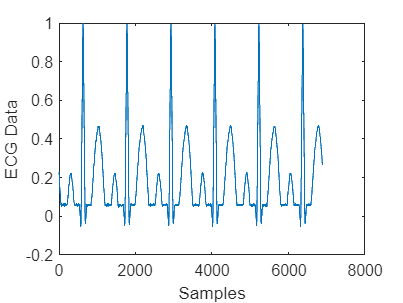

%Q3)

%1)
ECG_data = importdata('ECG_Data.txt');
figure;
plot(ECG_data);
xlabel('Samples')
ylabel('ECG Data')

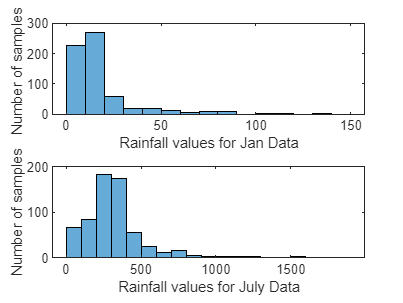

%2)
subplot(2,1,1);
Jan_data = importdata('RainFallIndia_Jan.txt');
h = histogram(Jan_data);
xlabel('Rainfall values for Jan Data')
ylabel('Number of samples ')

subplot(2,1,2)
Jul_data = importdata('RainFallIndia_July.txt');
h2 = histogram(Jul_data);
xlabel('Rainfall values for July Data')
ylabel('Number of samples')


%3
[y,Fs] = audioread('Track003.wav');
Fs

Fs = 44100

sound(y,Fs);

%Q4
% [y,Fs] = audioread('speech.wav');

%Q5
t = [0:0.001:5];
y1 = sin(2*pi*200*a*t);
y2 = sin(2*pi*220*a*t);
y3 = [y1,y2];
sound(y3,10000)

%Q6
s1 = sin(2*pi*220*t);
s2 = sin(2*pi*246*t);
s3 = sin(2*pi*261*t);
s4 = sin(2*pi*293*t);
s5 = sin(2*pi*329*t);
s6 = sin(2*pi*349*t);
s7 = sin(2*pi*392*t);
s = [s1,s2,s3,s4,s5,s6,s7];
sound(s,7000)

%Q7
[track3,Fs] = audioread("Track003.wav");
conv3 = importdata("ConvFile3.txt");
convolved_data = conv(track3,conv3);
audiowrite("Convolved_track_3.wav",convolved_data,44100);

new_wav_data = audioread("Convolved_track_3.wav");
sound(new_wav_data,44100)
%Since the frequencies audible seem to be only those in the higher end in
%the convolved track, the guess would be that the given filter is a high
%pass filter.